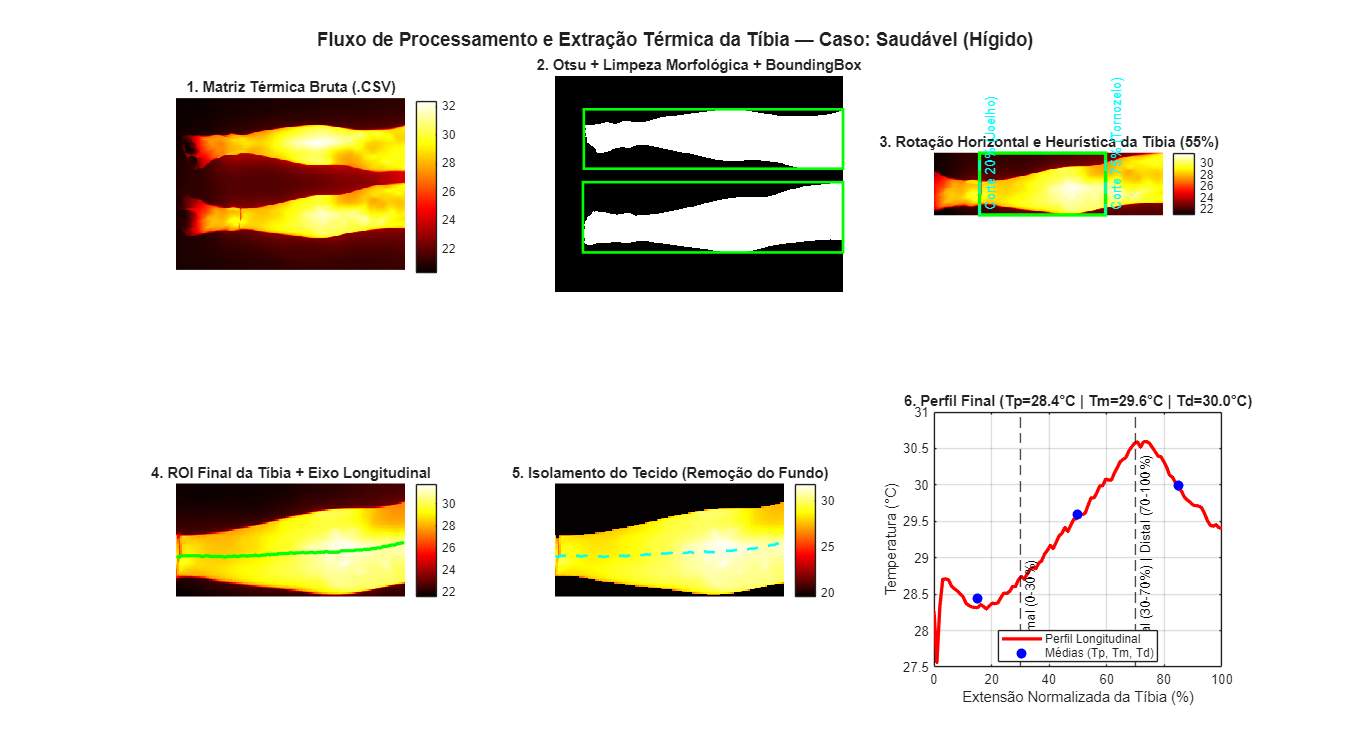

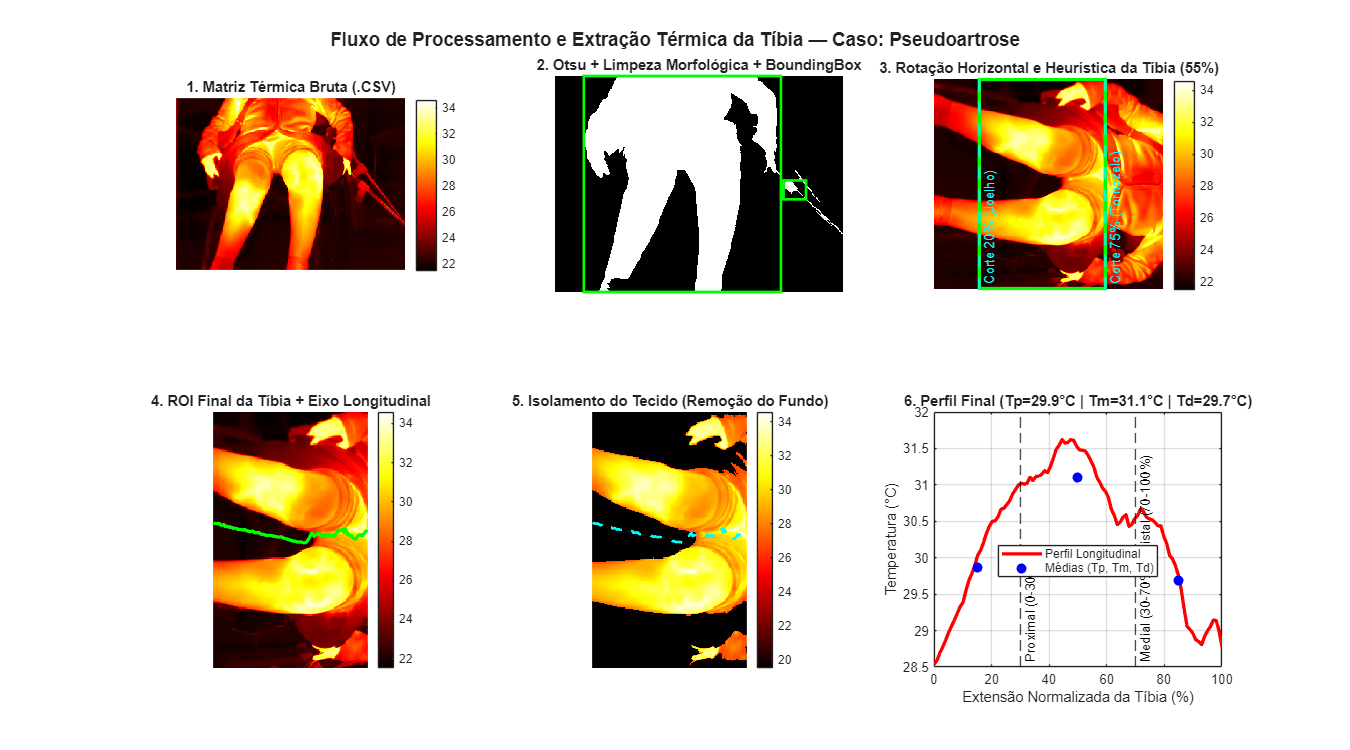

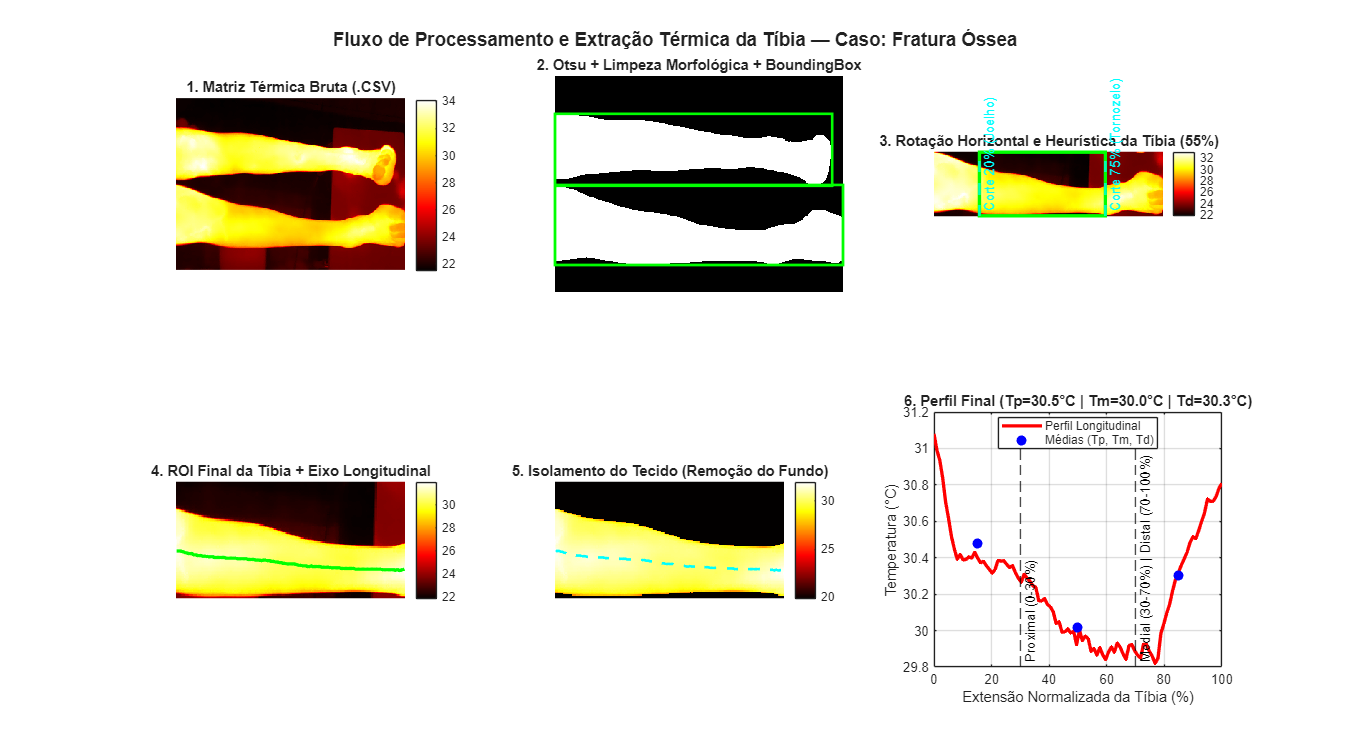

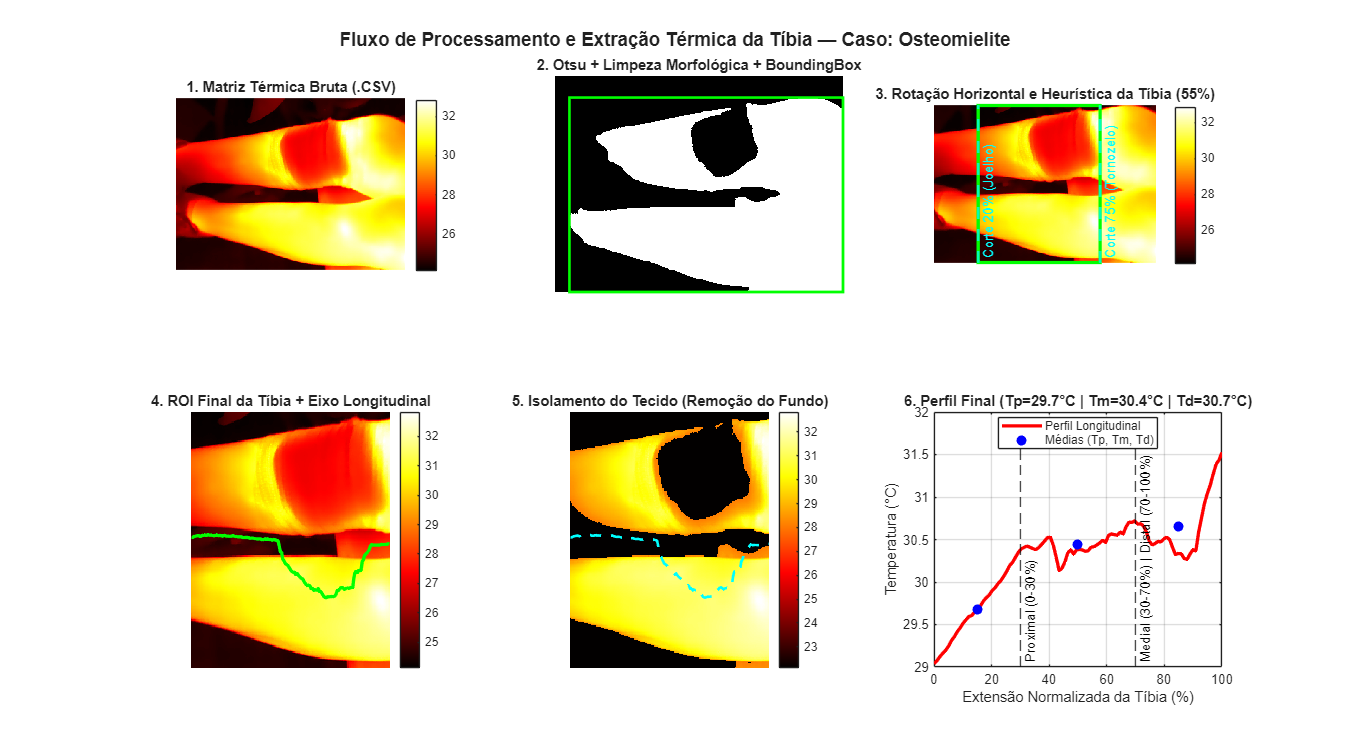

% =========================================================================
% SCRIPT DE VISUALIZAÇÃO PASSO A PASSO DO PIPELINE DE SEGMENTAÇÃO DA TÍBIA
% (Ideal para gerar figuras ilustrativas para a seção de Metodologia)
% =========================================================================
clc; clear; close all;

% 1. Caminho Principal do Dataset
pasta_principal = "D:\Faculdade\Artigo cientifico\data-20261007T205415Z-1-001\data";

banco_de_dados = imageDatastore(pasta_principal, ...
    'IncludeSubfolders', true, ...           
    'LabelSource', 'foldernames', ...
    'FileExtensions', '.csv', ...       
    'ReadFcn', @readmatrix);            

% 2. Seleciona automaticamente 1 arquivo válido de cada classe para demonstrar
classes_alvo = {'saudaveis', 'pseudoartrose', 'fraturas_osseas', 'osteomielite_tibia'};
nomes_exibicao = {'Saudável (Hígido)', 'Pseudoartrose', 'Fratura Óssea', 'Osteomielite'};

indices_escolhidos = [];
nomes_escolhidos = {};

for c = 1:length(classes_alvo)
    for i = 1:numel(banco_de_dados.Files)
        caminho = banco_de_dados.Files{i};
        % Ignora arquivos com fixador ou cicatrizados
        if contains(caminho, {'fixador', 'cicatrizada', 'cicatrizado'}, 'IgnoreCase', true)
            continue;
        end
        if contains(caminho, classes_alvo{c}, 'IgnoreCase', true)
            indices_escolhidos(end+1) = i;
            nomes_escolhidos{end+1} = nomes_exibicao{c};
            break; % Pega o primeiro exemplo válido da classe e passa para a próxima
        end
    end
end

% 3. Gera a Prancha do Pipeline para cada amostra selecionada
for k = 1:length(indices_escolhidos)
    idx_arquivo = indices_escolhidos(k);
    classe_nome = nomes_escolhidos{k};
    
    % Lê e limpa bordas totalmente NaN
    img_crua = readimage(banco_de_dados, idx_arquivo);
    img_crua = img_crua(~all(isnan(img_crua), 2), ~all(isnan(img_crua), 1));
    
    % Executa a função passo a passo que retorna todos os estágios intermediários
    [mascara_limpa, boxes, perna_alinhada, col_ini, col_fim, img_tibia, ...
     mascara_tibia, linha_y, perfil_100] = processar_passo_a_passo(img_crua);
    
    if isempty(img_tibia)
        continue;
    end
    
    % --- CRIAÇÃO DA FIGURA DO PIPELINE (6 ETAPAS) ---
    fig = figure('Name', sprintf('Pipeline de Tratamento - %s', classe_nome), ...
                 'Position', [80, 60, 1350, 750], 'Color', 'w');
    sgtitle(sprintf('Fluxo de Processamento e Extração Térmica da Tíbia — Caso: %s', classe_nome), ...
            'FontSize', 14, 'FontWeight', 'bold');
    
    % ETAPA 1: Imagem Térmica Crua
    subplot(2, 3, 1);
    imagesc(img_crua); colormap(gca, 'hot'); colorbar; axis image off;
    title('1. Matriz Térmica Bruta (.CSV)');
    
    % ETAPA 2: Máscara de Otsu + Morfologia + BoundingBox
    subplot(2, 3, 2);
    imshow(mascara_limpa); axis on; axis image off;
    hold on;
    for b = 1:size(boxes, 1)
        rectangle('Position', boxes(b,:), 'EdgeColor', 'g', 'LineWidth', 2);
    end
    hold off;
    title('2. Otsu + Limpeza Morfológica + BoundingBox');
    
    % ETAPA 3: Perna Isolada e Alinhada + Regra de Corte (20% a 75%)
    subplot(2, 3, 3);
    imagesc(perna_alinhada); colormap(gca, 'hot'); colorbar; axis image off;
    hold on;
    alt_p = size(perna_alinhada, 1);
    larg_p = size(perna_alinhada, 2);
    % Destaca a ROI da Tíbia com uma caixa verde e linhas de corte ciano
    xline(col_ini, 'c--', 'Corte 20% (Joelho)', 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom');
    xline(col_fim, 'c--', 'Corte 75% (Tornozelo)', 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom');
    rectangle('Position', [col_ini, 1, (col_fim - col_ini), alt_p-1], ...
              'EdgeColor', 'g', 'LineWidth', 2.5, 'LineStyle', '-');
    hold off;
    title('3. Rotação Horizontal e Heurística da Tíbia (55%)');
    
    % ETAPA 4: Tíbia Recortada (Final) + Linha Guia Central
    subplot(2, 3, 4);
    imagesc(img_tibia); colormap(gca, 'hot'); colorbar; axis image off;
    hold on;
    plot(1:length(linha_y), linha_y, 'g-', 'LineWidth', 2.5);
    hold off;
    title('4. ROI Final da Tíbia + Eixo Longitudinal');
    
    % ETAPA 5: Máscara Local da Tíbia (Separação Pele vs. Fundo Residual)
    subplot(2, 3, 5);
    % Cria uma visualização onde o fundo é escuro e a pele mantém a cor térmica
    img_tibia_isolada = img_tibia;
    img_tibia_isolada(~mascara_tibia) = min(img_tibia(:), [], 'omitnan') - 2; 
    imagesc(img_tibia_isolada); colormap(gca, 'hot'); colorbar; axis image off;
    hold on;
    plot(1:length(linha_y), linha_y, 'c--', 'LineWidth', 2);
    hold off;
    title('5. Isolamento do Tecido (Remoção do Fundo)');
    
    % ETAPA 6: Curva Longitudinal Interpolada (0-100%) e Divisão Anatômica
    subplot(2, 3, 6);
    x_100 = linspace(0, 100, 100);
    plot(x_100, perfil_100, 'r-', 'LineWidth', 2.5);
    hold on;
    xline(30, 'k--', 'Proximal (0-30%)', 'LabelVerticalAlignment', 'bottom');
    xline(70, 'k--', 'Medial (30-70%) | Distal (70-100%)', 'LabelVerticalAlignment', 'bottom');
    
    % Plota os pontos médios Tp, Tm, Td no gráfico
    Tp = mean(perfil_100(1:30), 'omitnan');
    Tm = mean(perfil_100(31:70), 'omitnan');
    Td = mean(perfil_100(71:100), 'omitnan');
    plot([15, 50, 85], [Tp, Tm, Td], 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 7);
    hold off;
    grid on; xlim([0 100]);
    xlabel('Extensão Normalizada da Tíbia (%)');
    ylabel('Temperatura (°C)');
    title(sprintf('6. Perfil Final (Tp=%.1f°C | Tm=%.1f°C | Td=%.1f°C)', Tp, Tm, Td));
    legend({'Perfil Longitudinal', '', '', 'Médias (Tp, Tm, Td)'}, 'Location', 'best');
end



% =========================================================================
% FUNÇÃO AUXILIAR QUE RETORNA TODAS AS ETAPAS INTERMEDIÁRIAS
% =========================================================================
function [mascara_limpa, boxes_detectados, img_perna, col_ini, col_fim, ...
          img_tibia, mascara_tibia, linha_centro_y, perfil_norm] = processar_passo_a_passo(img_termica)
      
    % Inicializa saídas caso falhe
    mascara_limpa = []; boxes_detectados = []; img_perna = []; col_ini = 1; col_fim = 1;
    img_tibia = []; mascara_tibia = []; linha_centro_y = []; perfil_norm = [];

    % 1. Normalização e Otsu Global
    min_val = min(img_termica(:), [], 'omitnan');
    max_val = max(img_termica(:), [], 'omitnan');
    if isempty(min_val) || max_val == min_val, return; end
    
    img_norm = (img_termica - min_val) ./ (max_val - min_val);
    img_norm(isnan(img_norm)) = 0;
    
    mascara = img_norm > graythresh(img_norm);
    mascara_limpa = bwareaopen(mascara, 50);
    mascara_limpa = imfill(mascara_limpa, 'holes');
    
    % 2. Bounding Boxes das Pernas
    propriedades = regionprops(mascara_limpa, 'Area', 'BoundingBox');
    if isempty(propriedades), return; end
    
    [~, idx] = sort([propriedades.Area], 'descend');
    num_pernas = min(2, length(propriedades));
    boxes_detectados = zeros(num_pernas, 4);
    for b = 1:num_pernas
        boxes_detectados(b, :) = propriedades(idx(b)).BoundingBox;
    end
    
    % Seleciona a primeira perna (maior área) para demonstrar o pipeline
    box_principal = boxes_detectados(1, :);
    if box_principal(4) > box_principal(3)
        % Perna em pé -> Recorta e gira -90 graus para deitar
        img_perna = imrotate(imcrop(img_termica, box_principal), -90);
    else
        % Perna já deitada -> Apenas recorta
        img_perna = imcrop(img_termica, box_principal);
    end
    
    % 3. Corte Heurístico da Tíbia (20% até 75% do comprimento)
    largura_total = size(img_perna, 2);
    col_ini = max(1, round(largura_total * 0.20));
    col_fim = min(largura_total, col_ini + round(largura_total * 0.55));
    img_tibia = img_perna(:, col_ini:col_fim);
    
    % 4. Extração da Máscara Local da Tíbia e Linha Central
    min_t = min(img_tibia(:), [], 'omitnan');
    max_t = max(img_tibia(:), [], 'omitnan');
    if max_t == min_t
        img_t_norm = zeros(size(img_tibia));
    else
        img_t_norm = (img_tibia - min_t) ./ (max_t - min_t);
    end
    img_t_norm(isnan(img_t_norm)) = 0;
    
    mascara_tibia = img_t_norm >= graythresh(img_t_norm);
    larg_tibia = size(img_tibia, 2);
    perfil_bruto = nan(1, larg_tibia);
    linha_centro_y = nan(1, larg_tibia);
    
    for x = 1:larg_tibia
        idx_pele = find(mascara_tibia(:, x));
        if ~isempty(idx_pele)
            linha_centro_y(x) = mean(idx_pele, 'omitnan');
            perfil_bruto(x) = mean(img_tibia(idx_pele, x), 'omitnan');
        end
    end
    
    % 5. Interpolação para 100 pontos (0 a 100%)
    validos = ~isnan(perfil_bruto);
    if sum(validos) > 5
        x_atual = linspace(0, 100, larg_tibia);
        x_padrao = linspace(0, 100, 100);
        perfil_norm = interp1(x_atual(validos), perfil_bruto(validos), x_padrao, 'linear', 'extrap');
    else
        perfil_norm = nan(1, 100);
    end
end